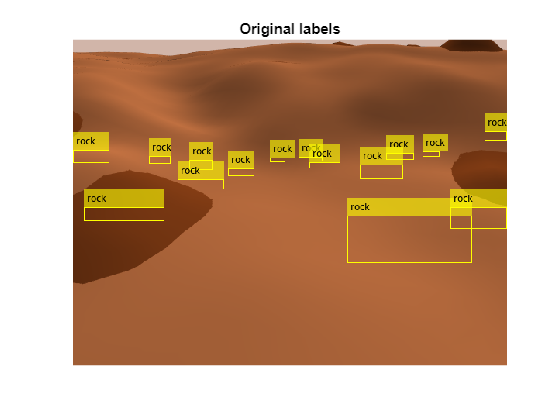

% This code can be used to generate rock bounding boxes using our trained
% model

%   Copyright 2022 The MathWorks, Inc.

% Load some of our images
load data
idx = 13;
img = imread("L1new.png");%imread(data.Filename{idx});
bboxes = data.rock(idx);

% Load our trained detector
load defaultDetector.mat

% Generate a prediction, which will be stored in predBboxes. We set a
% threshold of 0.45, which we determined after sweeping some values in the
% script InvestigateDetectionThreshold.m
[predBboxes, scores] = detector.detect(img, 'Threshold',.45);

% Plot results
originalImg = insertObjectAnnotation(img,"Rectangle",bboxes{1},"rock");
figure(121)%subplot(121)
imshow(originalImg);
title('Original labels');

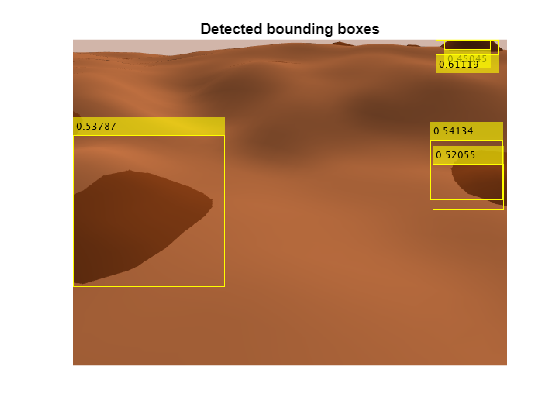


if(~isempty(predBboxes))
    detectedImg = insertObjectAnnotation(img,'rectangle',predBboxes,scores);
end
figure(122)%subplot(122);
imshow(detectedImg); 
title('Detected bounding boxes');